freqs = 1×6 cell array
    {[900000000]}    {[1.2000e+09]}    {[1.5000e+09]}    {[2.0000e+09]}    {[1.2000e+10]}    {[2.4000e+10]}


deltas = 1×4 cell array
    {[100]}    {[500]}    {[1000]}    {[1500]}


Signal generation

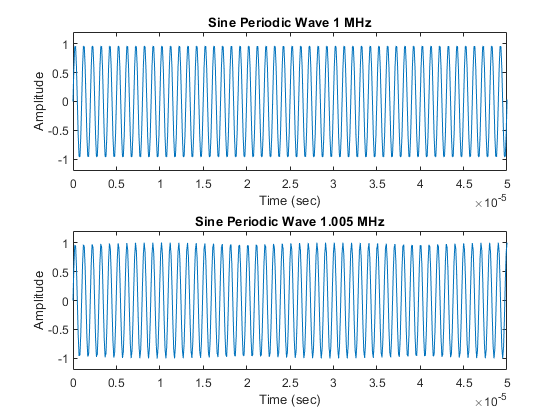

fs = 10e6;
t = 0:1/fs:1.5;

x1 = sin(2*pi*1e6*t); 
x2 = sin(2*pi*1.005e6*t);

subplot(2,1,1);
plot(t,x1);
axis([0 0.00005 -1.2 1.2]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Sine Periodic Wave 1 MHz');
subplot(2,1,2);
plot(t,x2);
axis([0 0.00005 -1.2 1.2]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Sine Periodic Wave 1.005 MHz'); 

Calculate doppler

x1fft = fft(x1);
x2fft = fft(x2);

L = length(t);      % Signal length
P = abs(x1fft/L);
P1 = P(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);

plot(x1fft,P1);

Error using plot
Vectors must be the same length.